# 선형 시스템을 위한 행렬 연산법

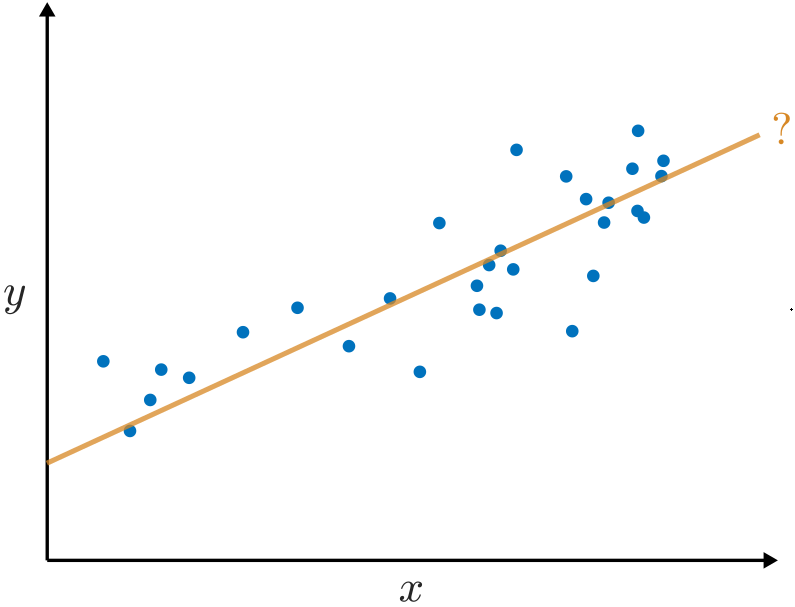                           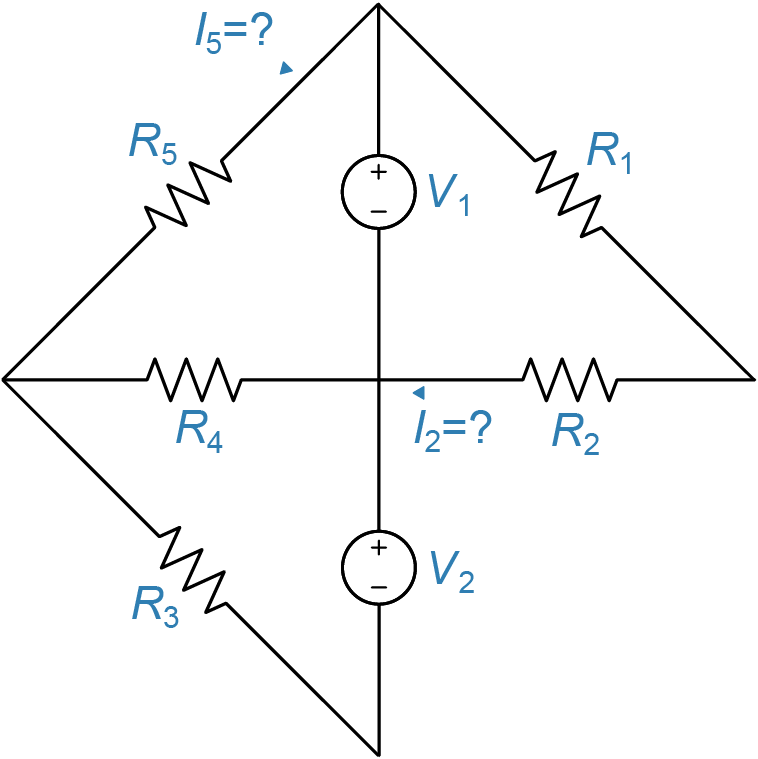

* 왼쪽 패널: 선형 회귀 - 어떤 직선이 데이터를 가장 잘 포착할까요? *

* 오른쪽 패널: 저항과 DC 전원으로 구성된 선형 회로. 각 분기를 통해 얼마나 많은 전류가 흐를까요? *

선형 회귀는 가장 널리 사용되는 수학적 기법 중 하나입니다. 물리학과 생물학 같은 전통적인 분야는 물론, 머신러닝 같은 현대적인 분야에서도 흔히 사용됩니다. 아마 여러분도 선형 회귀를 사용해 본 적이 있을 것입니다. 하지만 그것이 어떻게 계산되는지 알고 있나요?

작은 선형 회로의 가지에 흐르는 전류를 몇 가지 계산만으로 쉽게 결정할 수 있습니다. 그러나 복잡한 선형 회로에서는 전류가 많은 연결 경로를 통해 흐르므로 문제가 복잡해집니다. 그러면 수많은 복잡한 대수를 사용하지 않고 각 가지에 흐르는 전류를 어떻게 계산할 수 있을까요?

이 두 질문의 답은 선형대수의 행렬 연산법에 있습니다. 이 라이브 스크립트에서는 선형 시스템을 행렬 형태로 나타내고 분석하며 해결하는 방법을 배우게 됩니다. 직접 계산하는 방법과 MATLAB 함수를 사용하는 방법 모두를 다룰 것입니다.

 시작하기 전에: 

-  `VIEW` 탭을 선택하고 `Hide Code` 으로 전환합니다.

## 선형 방정식 시스템

** 정의**. *선형 방정식* 에는 변수의 배수 (예: $1.2x$) 또는 상수인 항만 포함됩니다.즉, 다음과 같은 형태로 표현할 수 있습니다. 

     
$$a_1x_1 + a_2x_2 + a_3x_3 +  \ldots = b$$


 여기서 $a_i$ 와 $b$ 는 상수이고 각 $x_i$ 는 변수입니다. 

** 정의**. *선형 방정식 시스템 * (혹은 *선형 시스템)은 *함께 고려되는 *선형 방정식의* *집합(set)입니다. *

-  선형 시스템은 해가 없거나, 해가 하나이거나 무한한 해를 가질 수 있습니다.

-  이 라이브 스크립트에서는 변수와 방정식의 수가 같은 시스템만 검사합니다. * 과결정 * (*overdetermined*, 미지수보다 방정식이 많음) 및 * 미결정 *  (*underdetermined*, 미지수보다 방정식이 적음) 시스템은 고려하지 않습니다. 

-  3차원 선형 시스템은 3개의 평면으로 시각화할 수 있습니다. 세 평면의 교점은 솔루션 집합을 나타냅니다. 

** 예제 **. 아래의 선형 시스템에 대해 

syms x y z a b c d
A = sym([0 1 1; 0 1 -2; a b c]);
bvec = sym([-1; 2; d]);
xvec = [x; y; z];
LinearSystem = A*xvec == bvec

$$LinearSystem = \left(\begin{array}{c} y+z=-1\\ y-2\,z=2\\ a\,x+b\,y+c\,z=d \end{array}\right)$$

 상수 $a$ , $b$ , $c$ , $d$ 의 값에 따라 이 시스템은 해가 없거나, 해가 하나이거나 무한한 해를 가질 수 있습니다.

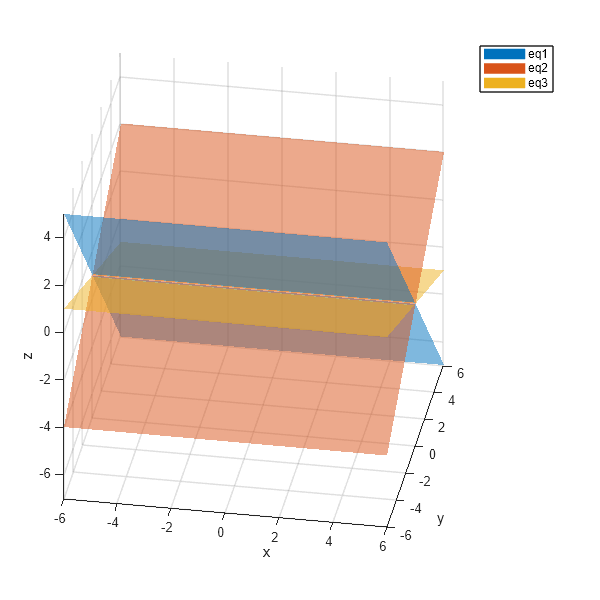

a =0; % 기본값: 1
b =-1; % 기본값: -1
c =-3; % 기본값: -1
d =3; % 기본값: -1
 
A(3,:) = [a b c];
bvec(3) = d;
lims = [-6 6];
Plot3DSystem(A,bvec,lims); % 이 함수는 평면을 플롯합니다.

  ** 실습. **

-  `a = -1` , `b = 0` , `c = 3` , `d = 1로 설정하고` 시스템을 그려보세요

-  플롯 위에 마우스를 올려 놓으면 도구 모음이 표시되고 회전 도구  를 사용하여 솔루션을 볼 수 있는 좋은 각도를 찾아보세요

-  데이터 팁 도구  를 사용하여 솔루션의 숫자 값을 추정합니다. 아래에 제공된 공간에 추정된 솔루션을 기록해보세요. 다음 연습에서 분석 솔루션과 비교하여 이를 검증합니다. 

MySltn = [""]

MySltn = ""

-  `a = 0`, `b = -1`, `c = -3`, `d = -2`를 설정하고 시스템을 플롯합니다. 솔루션은 무엇입니까? 

-  `a = 0`, `b = -1`, `c = -3`, `d = 3`를 설정합니다. 솔루션은 무엇입니까? 

** 연습 **. 제거 또는 대입을 사용하여 선형 시스템을 풉니다. 

    
$$\begin{array}{rl}
y+z&=-1\\
y-2\,z&=2\\
-x+3z&=1
\end{array}\
$$


ShowSolution = false;
if(ShowSolution)
    A = [0 1 1; 0 1 -2; -1 0 3];
    b = [-1; 2; 1];
    xvec = A\b;
    x = xvec(1)
    y = xvec(2)
    z = xvec(3)
end

 ** 생각해봅시다. ** 위에서 그래픽적으로 솔루션을 추정했습니다. 

if(exist("MySltn","var"))
    MySltn
else
    MySltn = ""
end

MySltn = ""

정답에 가까웠습니까? 

### **행렬 형태로 선형 시스템 작성**

**선형 시스템을 행렬 형태로 작성하는 이유는 무엇입니까? **

 행렬 표현은 여러가지 장점을 제공합니다(특히 대규모 방정식 시스템의 경우): 

-  행렬은 선형 시스템의 컴팩트한 표현을 제공합니다 

-  행렬은 솔루션 알고리즘을 표현하는 데 유용합니다 

-  선형 시스템의 풀이 가능성은 행렬 속성을 통해 확인할 수 있습니다 

-  행렬은 계산 코드를 작성하는 데 적합합니다 

-  행렬을 분해하면 대규모 시스템의 역학에 대한 의미 있는 통찰을 얻을 수 있습니다 

** 선형 시스템의 행렬 형태 **

 다음과 같이 행렬 형태의 $n$ 미지수가 있는 $n$ 선형 방정식 시스템을 작성할 수 있습니다: 

    
$$\mathbf{Ax} = \mathbf{b}$$


 이 표기법에서 $\mathbf{x}$는 변수의 열 벡터, $\mathbf{b}$는 상수 열 벡터, $\mathbf{A}$는 $n \times n$ 계수 행렬입니다. 

-  $\mathbf{A}$의 각 행은 방정식의 계수를 제공합니다. 

-  $\mathbf{b}$의 각 행은 방정식의 상수 우변을 제공합니다. 

** 예제 **. 아래 선형 시스템에 대해  

    
$$\begin{array}{rl}
-x+3z&=1\\
y+z&=-1\\
y-2\,z&=2
\end{array}\
$$


 (a) 해 변수 

    
$$\mathbf{x} = \left( \matrix{x \cr y \cr z} \right)$$


 를 사용하여 선형 시스템을 행렬 형태로 작성하세요 

(b) $\mathbf{Ax}$ 를 계산하여 행렬 형태가 대수 형태와 동등함을 확인하세요. 

** 해. (a) **

 1. $\mathbf{A}$ 의 첫 번째 행은 첫 번째 방정식에서 $x$ , $y$ , $z$ 의 계수를 제공합니다. 

        $\mathbf{A} = \left(\begin{array}{ccc}
-1 & 0 & 3\\
&  &  \\
 &  & 
\end{array}\right)$. 

 두 번째 계수는 첫 번째 방정식의 $y$ 항의 계수이므로 0입니다. $-x + \mathbf{0}y+3z =1

$. 

 2. 나머지 두 행도 비슷한 방식으로 구성됩니다. 

        
$$\mathbf{A} = \left(\begin{array}{ccc}
-1 & 0  &  3\\
0 & 1 & 1\\
0 & 1 & -2  
\end{array}\right)$$


 3. 상수 열 벡터 $\mathbf{b}$ 는 같은 방식으로 구성되며 각 상수는 해당 방정식의 우변을 나타냅니다. 

        
$$\mathbf{b} = \left( \matrix{1 \cr -1 \cr  2} \right)$$


 4. 이러한 정의에 따르면 $\mathbf{Ax} = \mathbf{b}$은 다음과 같습니다. 

        
$$ \left(\begin{array}{ccc}
-1 & 0  &  3\\
0 & 1 & 1\\
0 & 1 & -2  \\
\end{array}\right)\left( \matrix{x \cr y \cr z} \right)
=
 \left( \matrix{1 \cr -1 \cr 2} \right)$$


** (b) **

 좌변을 곱하면 

        
$$ \left(\begin{array}{ccc}
-x + 0y + 3z\\
0x  + 1y + 1z \\
0x  + 1y - 2z \\
\end{array} \right)
=
 \left( \matrix{1 \cr -1 \cr 2 } \right)$$


이 됩니다. 두 벡터의 각 행을 같게 하면 

        
$$\begin{array}{rl}
-x+3z&=1\\
y+z&=-1\\
y-2\,z&=2
\end{array}\
$$


이 됩니다. 이는 원래 시스템입니다. 

** 연습 **. 아래 선형 시스템에 대해  

    
$$\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}$$
  

 (a) $\mathbf{Ax} = \mathbf{b}$로 표현된 시스템에서 행렬 $\mathbf{A}$와 상수 벡터 $\mathbf{b}$의 계수는 어떻게 되나요?  

ShowSolution = false;
if(ShowSolution)
    syms a b d
    A = sym([1 1 1; 1 1 -1; -1 1 1]) 
    b = sym([2; -2; 2])
end

 (b) 행렬-벡터 곱 $\mathbf{Ax}$을 계산하고 시스템 $\mathbf{Ax} = \mathbf{b}$를 작성하세요. 결과가 원래 선형 시스템과 일치합니까? 

** 연습 **. 이 연습문제에서는 일반 행렬 시스템 $\mathbf{Ax} = \mathbf{b}$이 대수 방정식 집합과 동등함을 보여줍니다. 계수 행렬 $\mathbf{A}$, 해 벡터 $\mathbf{x}$, 상수 열 벡터 $\mathbf{b}$로 표현되는 일반적인 방정식 시스템 $\mathbf{Ax} = \mathbf{b}$에 대해 

1. MATLAB 명령을 사용하여 아래 공간에서 곱 $\mathbf{A}\mathbf{x}$을 계산해보세요. `A`, `x`, `b`은 MATLAB 작업 공간에서 정의됩니다. 

n =3;
A = sym("a",[n n]);
x = sym("x",[n 1]);
b = sym("b",[n 1]);
displayFormula("A*x = b")

$$\left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{2,1} & a_{2,2} & a_{2,3}\\ a_{3,1} & a_{3,2} & a_{3,3} \end{array}\right)\,\left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)=\left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3} \end{array}\right)$$

Ax = [ ]


Ax =

     []



 2. 아래 공간에 Symbolic Math Toolbox를 사용하여 $\mathbf{Ax}$을 $\mathbf{b}$와 같게 설정하세요.

  ** 전문가 팁. ** 기호적 동치의 경우 이중 동치( [`==`](https://www.mathworks.com/help/symbolic/eq.html)`)를 사용합니다.` 단일 동치 기호( `=)` 는 MATLAB에서 변수에 대한 할당을 나타내기 때문에 구별할 필요가 있습니다.

eqs = [ ]


eqs =

     []



-  다른 크기의 시스템을 보려면 $n$을 조정합니다. 

## 행렬 형태의 선형 시스템의 해를 구하기

행렬 형태로 선형 시스템을 손으로 푸는 한 가지 방법은 행 소거법(row-reduction)을 사용하는 것입니다. 행 소거법은 변수 제거(elimination)와 동일한 원리를 사용합니다. 시스템 $\mathbf{Ax=b{$를 고려해봅시다.

n =3;
 
A = sym("a",[n n]);
x = sym("x",[n 1]);
b = sym("b",[n 1]);
c = sym("c",[n 1]);
displayFormula("A*x = b")

$$\left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{2,1} & a_{2,2} & a_{2,3}\\ a_{3,1} & a_{3,2} & a_{3,3} \end{array}\right)\,\left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)=\left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3} \end{array}\right)$$

 행 소거법을 이용해 이 시스템의 해를 구하려면:

1. 시스템을 첨가 행렬(augmented matrix)의 형태로 작성합니다 $(\mathbf{A} \ \mathbf{b} )$:

if(false)
    Ab = [A b]
end

2. 행이 소거된 형태(row-reduced form)으로 행렬을 변형시켜 줍니다. 만약 시스템의 해가 유일하다면 소거된 형태는 다음과 같습니다.:

if(false)
    RowReducedForm = [eye(n,n), c]
end

위와 같은 형태로 첨가 행렬을 변형시켜주기 위해서 변수 제거(elimination)를 수행할 때 사용하는 것과 같은 연산을 사용합니다:

- 어떤 행에 상수 곱하기

- 한 행을 다른 행에 더하기 (필요한 경우 상수로 곱한 후 더하기)

- 어떤 행을 다른 행과 교환하기

이런 연산들은 종종 기본 행 연산 (*elementary row operations)*이라고도 부릅니다. 이 형태에서 시스템의 해는 마지막 열에 있는 $c_i$ 값이 됩니다. 고유한 해가 없는 경우 행 소거 형태가 다르게 나타날 것입니다.

 ** 생각해봅시다.. **

- 행이 소거된 형태의 시스템을 행렬 시스템의 형태로 쓰시오. 그런 다음, 행렬 계산을 수행해보십시오. 첨가 행렬의 마지막 열인 $c_i$가 해(solution)임을 보이시오.

- 기본 행 연산을 변수 제거(elimination)에 사용한 각 연산들이 기본 행 연산과 어떤 관계가 있는지 확인하시오.

- 시스템의 크기 $n$을 조정하시오. 행 소거 형태(row-reduced form)가 바뀝니까?

** 예제 **. 기본 행 연산을 이용해 아래의 선형 시스템의 해를 구하시오

    
$$\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}$$
 

**Solution. ** 행렬 표기에 대응하는 대수적 표기법이 참고를 위해 표시되어 있습니다. 특정 연산이 수행 및 반영된 것을 나타내기 위해 굵은 글꼴을 사용했습니다.

                                                                                행렬 표기                          대수적 표기

                                                                           
$$\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
2
\end{array}\right)$$
                 
$$\left\{\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}\right.$$


1. 행 1을 **행 3**에 더함 **→**                                     $\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
\mathbf 0& \mathbf 2 & \mathbf 2
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
\mathbf 4
\end{array}\right)$                    $\left\{ \begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
\mathbf{2y + 2z = 4}
\end{array}$

2. -1×행 1을 **행 2**에 더함 **→**                                $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & 0 & \mathbf{-2}\\
0 & 2 & 2
\end{array}\right|
\left.\begin{array}{c}
2\\
\mathbf{-4}\\
4
\end{array}\right)$                   $\left\{ \begin{array}{r}
x + y + z = 2
\\ 
\mathbf{- 2z = -4}
\\
2y + 2z = 4
\end{array}$

3. **행 2와 행 3**을 교체 **→**                                     $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & \mathbf 2 & \mathbf 2\\
0 & 0 & \mathbf {-2}
\end{array}\right|\ 
\left.\begin{array}{c}
2\\
\mathbf{4} \\
\mathbf {-4}
\end{array}\right)$                 $\left\{ \begin{array}{r}
x + y + z = 2
\\
\mathbf{2y + 2z = 4}
\\ 
\mathbf{- 2z = -4}
\end{array}$

4. **행 2**를 2로 나누고, **행 3**을 -2로 나눔 **→        **  $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & \mathbf  1 & \mathbf 1\\
0 & 0 & \mathbf{1}
\end{array}\right| \ 
\left.\begin{array}{c}
2\\
\mathbf {2}\\
\mathbf {2}
\end{array}\right)$                       $\left\{ \begin{array}{r}
x + y + z = 2
\\
\mathbf{y + z =  2}
\\ 
\mathbf{z = 2}
\end{array}$

5. **행 1**에서 행 2를 빼줌 **→**                                   $\left(\begin{array}{ccc}
\mathbf{1} & \mathbf{0} & \mathbf{0}\\
0 & 1 & 1\\
0 & 0 & 1
\end{array}\right| \ 
\left.\begin{array}{c}
\mathbf{0} \\
2 \\
2
\end{array}\right)$                      $\left\{ \begin{array}{r}
\mathbf{x = 0}
\\
y + z = 2
\\ 
z = 2
\end{array}$

6. **행2**에서 행 3을 빼줌**→**                                    $\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right| \ 
\left.\begin{array}{c}
0 \\
0 \\
2
\end{array}\right)$                      $\left\{ \begin{array}{r}
x = 0
\\
\mathbf{y  = 0}
\\ 
z = 2
\end{array}$

** 연습 **. 아래와 같이 행 소거가 해결된 행렬을 대수적 표현으로 바꿔 쓰시오.

                
$$\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right| \ 
\left.\begin{array}{c}
0 \\
0 \\
2
\end{array}\right)$$


if(false)
    displayFormula(["'x' = 0";"'y' = 0";"'z' = 2"])
end

** 정의**. 위 과정의 6번째 단계에서 얻은 해의 형태는 **기약행 사다리꼴 형태(reduced row echelon form)**로 알려져 있으며 다음과 같은 특성을 가지고 있습니다:

-  0이 아닌 각 행의 선행 항목은 이전 행의 선행 항목의 오른쪽에 있습니다. 

-  0이 아닌 행의 각 선행 항목은 1이고 **피벗(pivot)**이라고 합니다. 

-  모든 값이 0으로 구성된 행은 0이 아닌 행의 아래에 둡니다.

-  모든 피벗 열에서 피벗을 제외한 모든 항목은 0입니다. 

 고유한 솔루션이 있는 경우 축소 행 사다리꼴 형식은 단위 행렬입니다. 

** 연습 **. 이 연습문제에서는 행 소거법을 이용해 선형 시스템의 해를 구할 것입니다.

 (a) 아래의 연립 방정식을 행렬 형태로 작성하십시오.

    
$$\begin{array}{rl}
2x + y + z &= \ \ 2
\\ 
4x + 2y + z &= -2
\\
4x + 2y + 5z &= 10 \ \ 
\end{array}$$


 (b) 선형 시스템이 아래와 같이 도시되어 있습니다. 이 시스템은 어떤 해를 가질까요? 기약 행 사다리꼴 형태가 단위 행렬이 될까요?

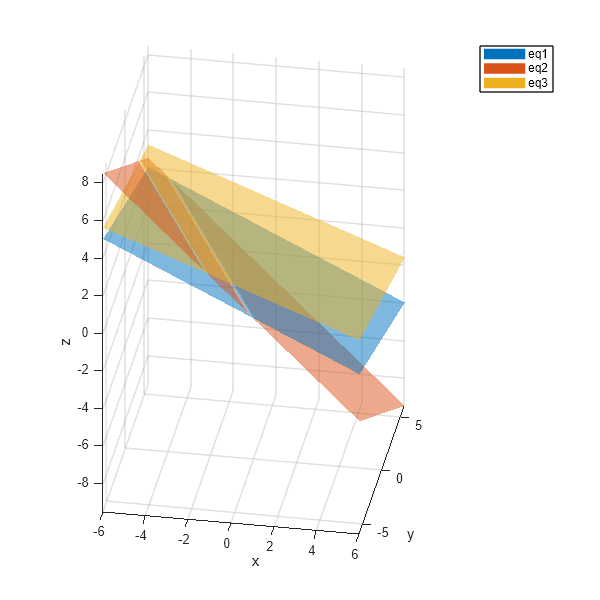

 
lims = [-6 6];
A = sym([2 1 4; 4 2 4; 2 1 5]);
bvec = sym([2; -2; 10]);
eqs = Plot3DSystem(A,bvec,lims); % 이 함수는 평면을 플롯합니다.

 (c) 시스템의 기약행 사다리꼴 형태를 구하시오.

ShowSolution = false;
if(ShowSolution)
    ReducedRowEchelonForm = sym(rref([A,bvec]))
end

(d) 축소된 행 사다리꼴 형태를 대수적 표기로 방정식을 다시 써보시오.

(e) 해는 무엇입니까?

## 정방 행렬의 역행렬

정방 행렬은 행과 열의 수가 같은 행렬을 말합니다. 이러한 행렬은 방정식과 미지수가 동일한 수의 시스템을 나타내기에 적합합니다. $n \times n$ 행렬 $\mathbf{A}$ 의 **역행렬**은 (존재할 경우) $\mathbf{A}^{-1}$로 표기되며 다음을 만족합니다:

    
$$\mathbf{A}^{-1} \mathbf{A} = \mathbf{I}$$


여기서 $I$는 $n \times n$ 단위 행렬입니다. 모든 정방 행렬이 역행렬을 가지는 것은 아닙니다.

### **역행렬을 이용한 선형 시스템의 해**

선형 시스템 $\mathbf{Ax} = \mathbf{b}$ 의 해(존재하는 경우)는 행 소거 연산을 통해 계산할 수 있습니다. 그러나 하나 이상의 $\mathbf{b}$에 대한 해를 계산하려면 임의의 $\mathbf{b}$에 대한 해를 작성한 후 필요에 따라 특정 $\mathbf{b}$에 대한 해를 평가하는 것이 편리합니다. 행렬 역함수는 이 목적에 적합합니다.

$\mathbf{A}$가 가역 $n\times n$ 행렬이고 임의의 상수 벡터 $\mathbf{b}$에 대해 $\mathbf{Ax}=\mathbf{b}$를 풀고자 한다고 가정해 봅시다:

              
$$\mathbf{Ax} = \mathbf{b}$$


        $\mathbf A^{-1} \mathbf{Ax} = \mathbf{A}^{-1} \mathbf{b}$             1. 방정식의 양변에 $\mathbf{A}^{-1}$을 왼쪽에서 곱합니다..

               $\mathbf{Ix} = \mathbf{A}^{-1} \mathbf{b}$             2. 행렬 역함수의 정의를 사용합니다: $\mathbf{A}^{-1} \mathbf{A} = \mathbf{I}$.

                $\mathbf{x} = \mathbf{A}^{-1} \mathbf{b}$             3. 단위 행렬의 정의에 따라 $\mathbf{Ix} = \mathbf{x}$가 됩니다.

이는 임의의 상수 오른쪽 벡터 $\mathbf{b}$에 대해 선형 시스템의 해를 $\mathbf{x=A^{-1} b}$로 계산할 수 있음을 의미합니다. 이 과정에서 필요한 유일한 계산은 행렬 곱셈 $\mathbf{A^{-1} b}$입니다.

** 연습 **. 행렬 $\mathbf{A}$, $\mathbf{C}$ 및 $\mathbf{D}$가 아래와 같습니다. 

 
A = sym([4 -1 0.5; 0.5 0.1 -0.5; 1 4 -0.5])

$$A = \left(\begin{array}{ccc} 4 & -1 & \frac{1}{2}\\ \frac{1}{2} & \frac{1}{10} & -\frac{1}{2}\\ 1 & 4 & -\frac{1}{2} \end{array}\right)$$

C = inv(A + [-2 0 0; 0 0 0; 0 0 0])

$$C = \left(\begin{array}{ccc} \frac{13}{34} & \frac{5}{17} & \frac{3}{34}\\ -\frac{5}{102} & -\frac{5}{17} & \frac{25}{102}\\ \frac{19}{51} & -\frac{30}{17} & \frac{7}{51} \end{array}\right)$$

D = inv(A)

$$D = \left(\begin{array}{ccc} \frac{13}{60} & \frac{1}{6} & \frac{1}{20}\\ -\frac{1}{36} & -\frac{5}{18} & \frac{1}{4}\\ \frac{19}{90} & -\frac{17}{9} & \frac{1}{10} \end{array}\right)$$

 이 행렬들은 MATLAB 작업 공간에도 정의됩니다. 

(a) 아래 마련된 두 공란에서 MATLAB 명령어를 이용해 행렬 $\mathbf{C}$ 혹은 $\mathbf{D}$가 행렬 $\mathbf{A}$의 역행렬인지 확인하시오.

(b) 아래의 (숨겨진) 코드에서는 상수 열벡터 $\mathbf{b}$가 정의되어 있습니다. 행렬 $\mathbf{C}$ 혹은 $\mathbf{D}$를 이용해 아래의 공란에 코드를 작성하여 $\mathbf{Ax=b}$의 해를 구하시오.

b = sym([-2; 1; -3])

$$b = \left(\begin{array}{c} -2\\ 1\\ -3 \end{array}\right)$$

x = [ ]


x =

     []



 (c) 제공된 공간에서 행렬 곱 $\mathbf{Ax}$를 계산하여 $\mathbf{x}$에 관한 시스템 $\mathbf{Ax} = \mathbf{b}$을 풀고 결과가 $\mathbf{b}$와 같은지 확인하세요.

### **행 소거법으로 역행렬 계산하기**

행 소거 연산을 사용하여 행렬 $\mathbf{A}$의 역행렬을 계산할 수 있습니다.이를 수행하려면 다음을 수행합니다. 

 1. 행렬을 단위 행렬과 함께 첨가 행렬(augmented matrix)로 작성합니다. $(\mathbf{A} \ \mathbf{I})$. 예를 들어, 3x3 행렬의 경우 다음과 같습니다. 

    
$$\left(\begin{array}{ccc}
a_{11} & a_{12} & a_{13}\\
a_{21} & a_{22} & a_{23}\\
a_{31} & a_{32} & a_{33}\\
\end{array}
\  \ \begin{array}{ccc}
1 & 0 & 0 \\
0 & 1 & 0 \\
0 & 0 & 1 
\end{array}\right)$$


 2. 행 연산을 사용하여 $\mathbf A$를 단위 행렬로 변환합니다. 연산은 오른쪽 행렬에 인코딩되어 $\mathbf A^{-1}$ 을 생성합니다. 

    
$$\left(\begin{array}{ccc}
1 & 0 & 0 \\
0 & 1 & 0 \\
0 & 0 & 1 
\end{array}
\  \ \begin{array}{ccc}
 &  &  \\
 & \mathbf{A}^{-1} &  \\
 &  & 
\end{array}\right)$$


 역행렬이 없으면 이 형태를 얻을 수 없습니다. 아래에서 이에 대해 더 자세히 설명합니다. 

** 예제 **. 행 연산을 사용하여 $\mathbf A$의 역행렬을 풉니다. 

** Solution. ** 솔루션의 다음 단계를 보려면 슬라이더를 앞으로 이동합니다. 

kstep = 1;

    
$$\mathbf A = 
\left(\begin{array}{ccc}
0.5 &  2 & 1\\
1 & 2 & -1\\
-1 & 0 & -4
\end{array}\right)
$$


InvDialogue(kstep);

$$\mathrm{1. A와 I를 하나의 첨가 행렬로 함께 작성합니다.}$$

$$\left(\begin{array}{cccccc} \frac{1}{2} & 2 & 1 & 1 & 0 & 0\\ 1 & 2 & -1 & 0 & 1 & 0\\ -1 & 0 & -4 & 0 & 0 & 1 \end{array}\right)$$

** 연습 문제 **. 위의 예에서 계산된 $\mathbf{A}^{-1}$가 $\mathbf A$의 역행렬인지 직접 확인합니다( $\mathbf A^{-1} \mathbf A$가 $\mathbf I$와 같은지 확인). 

            $\mathbf A = 
\left(\begin{array}{ccc}
0.5 &  2 & 1\\
1 & 2 & -1\\
-1 & 0 & -4
\end{array}\right)
$ , $\mathrm{\mathbf A^{-1} =\ }\mathrm{}\left(\begin{array}{ccc}
-1 & 1 & -\frac{1}{2}\\
\frac{5}{8} & -\frac{1}{8} & \frac{3}{16}\\
\frac{1}{4} & -\frac{1}{4} & -\frac{1}{8}
\end{array}\right)$

### **정사각 행렬의 역행렬 공식**

 2x2 행렬의 역행렬은 

        $\mathbf A = \left(\begin{array}{cc}
a & b\\
c & d
\end{array}\right)$ 입니다. 

 3x3 행렬의 역행렬은

        $\mathbf A =
\left(\begin{array}{ccc}
a & b & c\\
d & e & f\\
g & h & i
\end{array}\right)$ 입니다. 

 더 큰 행렬의 경우 공식이 꽤 복잡해집니다. 

Show4x4 = false;
if(Show4x4)
    A = sym("a",[4,4])
    inv(A)
    disp("If this makes you feel dizzy, you can uncheck the box.")
end

  ** 실습. **

-  행 축소를 사용하여 2x2 행렬의 일반 역행렬을 직접 유도해 보세요. $\mathbf A = \left(\begin{array}{cc}
a & b\\
c & d
\end{array}\right)$ 

-  행렬 곱을 직접 계산하여 2x2 행렬 역행렬 공식을 확인합니다. $\mathbf A^{-1} \mathbf A$ 

 ** 생각해봅시다. **

-  많은 정사각 행렬의 경우 역행렬이 존재하지 않습니다. 일반 공식이 존재하기 때문에 이 사실이 약간 놀랍습니다. 위에 나온 2x2와 3x3 행렬의 역행렬 공식을 검토해 보세요. 어떤 조건에서 정의되지 않은 역행렬이 생길까요? 

## **정방 행렬의 가역성**

** 정의**. 역행렬이 존재하면 $n\times n$ 행렬은 가역적이라고 합니다. ** 역행렬 공식을 살펴보면 행렬의 가역성에 대한 통찰을 얻을 수 있습니다. 2x2 행렬의 역행렬을 고려해 보겠습니다. **

    
$$\mathbf A^{-1} = \frac{1}{ad - bc} \left(\begin{array}{cc}
d & -b\\
-c &a
\end{array}\right)$$


 계수 항의 분모가 0인 경우, 즉 $ad - bc = 0$ 행렬의 역행렬은 정의되지 않습니다(행렬의 항은 $\frac{1}{0}$ 또는 $\frac{0}{0}$ ). 

 마찬가지로 $3 \times 3$ 의 경우 

    $\mathbf A^{-1} =
\frac{1}{a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g}
\left(\begin{array}{ccc}
e\,i-f\,h & -b\,i+c\,h& b\,f-c\,e\\
-d\,i+f\,g& a\,i-c\,g & -a\,f+c\,d\\
d\,h-e\,g & -a\,h+b\,g & a\,e-b\,d
\end{array}\right)$. 

 행렬의 역행렬은 $a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g = 0$ 인 경우 정의되지 않습니다.

 ** 생각해봅시다. **

-  4x4 행렬 역행렬에 대해서도 비슷한 조건이 존재합니까? 

Show4x4 = false;
if(Show4x4)
    A = sym("a",[4 4])
    inv(A)
    disp("If this makes you feel dizzy, you can uncheck the box.")
end

### 행렬 행렬식

행렬식은 정사각( $n \times n$ ) 행렬의 가역성을 특징짓는 스칼라 값입니다. 

-  행렬식은 정사각이 아닌 행렬에 대해서는 정의되지 않습니다. 

-  수직선 $| \cdot |$은 행렬의 행렬식을 나타냅니다. 

** 2x2 행렬의 행렬식 **

 2x2 행렬의 행렬식은 

    $|\mathbf{A}| = \left| \matrix{a & b \cr c & d } \right| = ad - bc$ 입니다. 

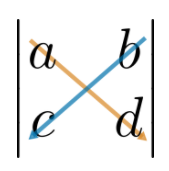

* 2x2 행렬의 행렬식은 대각(diagonal) 성분의 곱에서 비대각(off-diagonal) 성분 곱을 뺀 것으로 생각할 수 있습니다. *

더 큰 행렬의 행렬식은 부분 행렬의 행렬식을 사용하여 알고리즘적으로 계산할 수 있습니다. 이 프로세스를 라플라스 전개라고 합니다. 

** 3x3 행렬의 행렬식 **

 라플라스 전개를 사용하면 2x2 부분 행렬을 사용하여 3x3 행렬의 행렬식을 계산할 수 있습니다. 

    
$$|\mathbf{A}|= \left| \matrix{a & b & c \cr d & e & f \cr g & h & i } \right| = a \left| \matrix{ e & f \cr h & i } \right| - b \left| \matrix{ d & f \cr g & i } \right|  +c \left| \matrix{ d & e \cr g & h } \right|$$


 위에 정의된 공식을 사용하여 2x2 부분 행렬의 행렬식을 계산할 수 있습니다. 

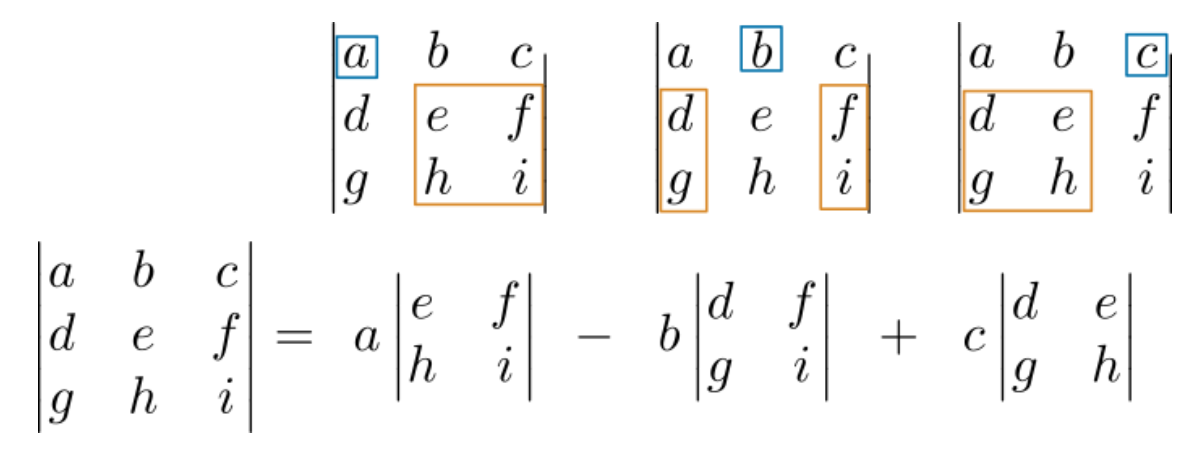

* 3x3 행렬의 라플라스 전개 개략도. 첫 번째 행에서 한 요소를 선택한 다음 다른 행과 열에서 부분 행렬을 선택하는 것을 시각화합니다. 또한 공식의 부호 변경에 주의하세요. *

 부분 행렬의 행렬식을 전개하면 3x3 행렬식 공식이 생성됩니다. 

    
$$|\mathbf{A}|= a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g$$


 마찬가지로 더 큰 행렬을 확장하여 더 작은 행렬로 분해할 수 있습니다. 그러나 이러한 경우에는 일반적으로 수치 소프트웨어가 사용됩니다. 

 ** 예제**. 라플라스 전개를 사용하여 $A$의 행렬식을 계산합니다. 크기를 조정할 수 있습니다. 

n = 2; 
 
A = sym(randi(9,n,n));
displayFormula(["'A = '", "A"]) 

$$\mathrm{A =}\left(\begin{array}{cc} 8 & 2\\ 9 & 9 \end{array}\right)$$

ShowSolutiond = false;
if(ShowSolutiond)
    DetA = det(A)
end

** 행렬식의 가역 조건. ** 정사각 $n\times n$ 행렬식은 오직 그 ** 행렬식 **이 0이 아닌 경우에만 가역적입니다. 

-  정사각 행렬의 가역성은 현재 논의 범위를 벗어나는 다른 많은 행렬 속성과 관련될 수 있습니다. 

** 행렬식의 가역 조건 이해 **

 2x2 행렬식을 고려해 보겠습니다: $ad - bc$. 이것은 역행렬의 분모에서 발견되는 것과 동일한 표현식입니다. 즉, 역행렬을 정의하려면 $| \mathbf A| = ad - bc$이 0이 아니어야 합니다. 역행렬에 대한 공식을 다음과 같이 쓸 수도 있습니다. 

    $\mathbf A^{-1} = \frac{1}{|\mathbf A|} \left(\begin{array}{cc}
d & -b\\
-c &a
\end{array}\right)$. 

 이 개념은 고차원 행렬로 확장됩니다. 3x3의 경우 행렬식은 $|\mathbf A| = a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g$ 입니다. 따라서 역행렬의 공식은 

    $\mathbf A^{-1} =
\frac{1}{|\mathbf A|}
\left(\begin{array}{ccc}
e\,i-f\,h & -b\,i+c\,h& b\,f-c\,e\\
-d\,i+f\,g& a\,i-c\,g & -a\,f+c\,d\\
d\,h-e\,g & -a\,h+b\,g & a\,e-b\,d
\end{array}\right)$ , 

 이며 이는 오직 $|\mathbf A| \neq 0$ 일 때만 잘 정의됩니다. 

** 연습문제 **. 

 (a) 행렬이 가역적인지 확인합니다. 


$$\mathbf A = 
 \left(\begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
8 & 9 & 10
\end{array}\right)$$
        
$$\mathbf{B} = 
 \left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right)$$
          
$$\mathbf{C} = 
\left(\begin{array}{ccc}
1 & 0.5 & -1\\
0 & 2 & 1\\
-4 & 1 & 1
\end{array}\right)$$
        

ShowSolution = false;
As = [1 2 3; 4 5 6; 8 9 10];
Bs = [1 1 1; 1 0 0; 0 0 1];
Cs = [1 0.5 -1; 0 2 1; -4 1 1];
if(ShowSolution)
    disp("|A| = " + string(det(sym(As))) + " so the matrix is not invertible.")
    disp("|B| = " + string(det(sym(Bs))) + " so the matrix is invertible.")
    disp("|C| = " + string(det(sym(Cs))) + " so the matrix is invertible.")
end

 (b) 공식이나 행 축소를 사용하여 가역 행렬의 역을 계산합니다. 

 (c) 아래의 MATLAB에서 행렬 $\mathbf{A}$ , $\mathbf{B}$ , $\mathbf{C}$ 를 정의합니다. 세미콜론은 행을 구분하는 데 사용되고 공백이나 쉼표는 열을 구분하는 데 사용됩니다. 예: `[0 1; 2 3]`. 

A = sym([ ])

 
A =
 
[ empty sym ]
 


B = sym([ ])

 
B =
 
[ empty sym ]
 


C = sym([ ])

 
C =
 
[ empty sym ]
 


  ** 전문가 팁 ** :   MATLAB을 사용하여 역을 계산할 수도 있습니다. MATLAB에서 `inv(C)` 구문을 사용하여 행렬 C의 역을 계산할 수 있습니다. 아래의 가역 행렬의 역행렬을 계산해 보세요. 

 (d) `inv`를 사용하여 아래 각 행렬의 역행렬을 계산합니다. 비가역 행렬에 대한 해는 무엇입니까? 

Ainv = [ ]


Ainv =

     []



Binv = [ ]


Binv =

     []



Cinv = [ ]


Cinv =

     []



** 연습문제 **. 이 연습문제에서는 역행렬을 사용하여 

    $\mathbf A = \left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right)$를 사용하여 선형 시스템 $\mathbf{Ax} = \mathbf{b}$의 해를 계산합니다. 

 (a) 행 축소 또는 3x3 행렬 공식을 사용하여 $\mathbf{A}^{-1}$를 계산합니다. 

ShowSolutionA = false;
A = sym([1 1 1; 1 1 -1; -1 1 1]);
if(ShowSolutionA)
    Ainv = inv(A) 
end

 (b) 

    $\mathbf{b} = \left( \matrix{ 1 \cr 0 \cr -1 } \right)$를 사용하여 행렬 곱 $\mathbf{A}^{-1} \mathbf{b}$를 계산하여 시스템을 풉니다. 

ShowSolutionB = false;
b = [1; 0; -1];
Ainv = inv(A);
if(ShowSolutionB)
    x=A\b
end

 (c) 

    $\mathbf{b} = \left( \matrix{ 2 \cr -5 \cr 10 } \right)$를 사용하여 $\mathbf{x}$에 대한 시스템을 풉니다. 

ShowSolutionC = false;
b = [2; -5; 10];
if(ShowSolutionC)
    x=A\b
end

### **행렬을 기준으로 한 선형 시스템 해의 특성화**

행렬 표현의 중요한 특징은 방정식 시스템에 고유한 해가 있는지 빠르게 계산할 수 있다는 것입니다. $n$개의 방정식과 $n$개의 미지수가 있는 선형 시스템을 고려해 보겠습니다. 이것은 다음과 같은 행렬 형태로 표현될 수 있습니다. 

    
$$\mathbf{Ax} = \mathbf{b}$$


 이 시스템의 경우 다음은 동치입니다(이는 ** 가역 행렬 정리 ** 의 일부입니다). 

- $\mathbf{A}$ 는 가역입니다. 

- $|\mathbf{A}|$ 는 0이 아닙니다. 

-  선형 시스템은 $\mathbb{R}^n$ 의 모든 $\mathbf{b}$ 에 대해 고유한 해를 갖습니다. 

 시스템에 고유한 해가 있는지 확인하려면 시스템을 행렬 형태로 표현한 다음 $|\mathbf{A}|$ 를 계산할 수 있습니다. 행렬식이 0이 아니면 시스템은 모든 $\mathbf{b}$ 에 대해 고유한 해를 갖습니다. 

** 연습 **. (1) 시스템을 행렬 형태로 작성하고 (2) 계수 행렬의 행렬식을 계산하여 시스템에 고유한 해가 있는지 확인합니다. 

 (a) $\begin{array}{r}
2x +y = 2
\\ 
x - y  = 10
\end{array}$  

ShowSolutionA = false;
syms x y z
A = sym([2 1; 1 -1]);
b = sym([2; 10]);
xvec = [x; y];
if(ShowSolutionA)
    displayFormula([char(A),char(xvec),"' = '",char(b)]);
    disp("|A| = " + string(det(A)) + " which is nonzero. This implies that the system has a unique solution.")
end

 (b) $\begin{array}{r}
2x +y + 4z = 2
\\ 
x - z = 10
\\ 
-3x + 2 y - z = 11
\end{array}$  

ShowSolutionB = false;
A = sym([2 1 4; 1 0 -1; -3 2 -1]);
b = sym([2; 10; 11]);
xvec = [x; y; z];
if(ShowSolutionB)
    displayFormula([char(A),char(xvec),"' = '",char(b)]);
    disp("|A| = " + string(det(A)) + " which is nonzero. This implies that the system has a unique solution.")
end

## **MATLAB에서 선형 시스템 작업하기**

행 소거법이나 역행렬을 사용하여 작은 방정식 시스템은 손으로 풀기 어렵지 않습니다. 하지만 시스템에 수십, 수백, 심지어 수천 개의 변수가 있다면 어떻게 될까요?

아래의 슬라이더를 조정하여 $\mathbf{Ax} = \mathbf{b}$ 시스템의 크기를 선택합니다. 

n = 15;
A = randi(20,[n n])-10;
b = randi(20,[n 1])-10;
x = sym("x",[n 1]);
displayFormula([char(sym(A)),char(sym(x)),"' = '",char(sym(b))]);

$$\left(\begin{array}{ccccccccccccccc} 3 & 10 & -8 & 6 & 8 & 0 & 9 & 5 & 7 & -7 & 0 & -8 & 4 & 6 & 7\\ -8 & 4 & 7 & -4 & 10 & -2 & -7 & 0 & 8 & 8 & 0 & -5 & -6 & 3 & -6\\ -4 & -9 & 4 & 4 & 1 & 7 & 2 & -8 & -8 & 3 & -3 & -2 & -2 & -2 & -5\\ 1 & 7 & -3 & 4 & -7 & 2 & 0 & -5 & -2 & -2 & 9 & 7 & 3 & 7 & -6\\ 10 & 9 & 10 & -6 & -7 & 1 & -9 & 9 & -4 & 1 & -2 & -9 & 6 & 1 & -5\\ 10 & 4 & -9 & -7 & -4 & 9 & -3 & -6 & 7 & -1 & -7 & -9 & -8 & -2 & -1\\ -6 & 6 & -1 & 0 & 7 & -4 & -6 & 7 & -1 & -8 & 6 & -6 & 9 & 9 & -3\\ 10 & 5 & -2 & 10 & -4 & 6 & 6 & 1 & 9 & -5 & -2 & 3 & 6 & 8 & 9\\ 10 & -2 & 6 & -3 & 7 & 6 & -3 & 10 & -6 & -7 & -5 & 5 & 0 & 2 & -1\\ 0 & 4 & 6 & 2 & -5 & -2 & 1 & -8 & -4 & -6 & -1 & 3 & -1 & 3 & -6\\ 7 & -6 & -6 & -5 & 9 & 2 & -6 & -1 & -7 & -5 & -8 & 0 & -1 & 2 & 9\\ -7 & 5 & 0 & 6 & -3 & -8 & 3 & -7 & -7 & -1 & -7 & 1 & -3 & -5 & 10\\ -1 & -9 & -1 & -4 & -6 & -8 & -4 & 10 & 8 & -9 & 9 & -4 & 1 & -3 & -1\\ 9 & -4 & 3 & 1 & -4 & 1 & 4 & -9 & 2 & 9 & 10 & 5 & 1 & 0 & -7\\ 6 & -9 & 5 & 4 & 3 & 6 & 4 & 6 & 1 & 9 & 2 & -6 & 7 & -5 & -4 \end{array}\right)\left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4}\\ x_{5}\\ x_{6}\\ x_{7}\\ x_{8}\\ x_{9}\\ x_{10}\\ x_{11}\\ x_{12}\\ x_{13}\\ x_{14}\\ x_{15} \end{array}\right)=\left(\begin{array}{c} -1\\ 2\\ -4\\ 3\\ 5\\ -5\\ -7\\ -4\\ -3\\ -1\\ 1\\ -8\\ -4\\ 7\\ -9 \end{array}\right)$$

 이 시스템을 수동으로 푸는 것은 실행 가능한 옵션이 아닙니다. 수치 소프트웨어를 사용하여 시스템을 풀어야 합니다. MATLAB에서 행렬과 벡터를 사용하여 선형 시스템 $\mathbf{Ax} = \mathbf b$를 정의하고 내장 함수를 사용하여 시스템을 풀  있습니다. 수치적 접근 방식과 기호적 접근 방식의 두 가지 방법이 있습니다. 이 섹션에서는 두 가지 접근 방식을 모두 살펴보겠습니다. 일반적으로 행렬을 다루는 동일한 기본 함수(예: `inv` 및 `det` )는 기호 행렬과 수치적 행렬 모두에 적용됩니다. 이 섹션에서 솔루션 벡터는 다음과 같이 표현됩니다. 

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n} \right)$. 

** 연습 **. 이 연습문제에서는 수치적 행렬을 사용하여 선형 시스템을 분석하고 풉니다. 제공된 공간에 있는 MATLAB 명령을 사용하여 작업을 수행합니다. 

   ** Task 1. ** 위에서 정의한 시스템 $\mathbf{Ax} = \mathbf{b}$에 고유한 솔루션이 있는지 확인합니다. 행렬 $\mathbf{A}$은 변수 `A`에 저장되고 벡터 $\mathbf{b}$는 `b`에 저장됩니다. 

** 힌트 ** : MATLAB 행렬식 함수 [`det`](https://www.mathworks.com/help/matlab/ref/det.html)를 사용합니다. 

answer = 0;
IsEqualCheck(answer,det(A)~=0);

   ** Task 2. ** `A`의 역행렬을 계산합니다. 

InvA = [ ]


InvA =

     []



 
IsEqualCheck(inv(A),InvA);

** 힌트 ** : [`inv`](https://www.mathworks.com/help/matlab/ref/inv.html). 

   ** Task 3. ** 역행렬 InvA를 사용하여 $\mathbf{Ax} = \mathbf{b}$의 솔루션을 계산합니다. 

xSoln1 = [ ]


xSoln1 =

     []



 
IsEqualCheck(xSoln1,inv(A)*b);

 MATLAB에서 선형 시스템을 푸는 데는 역행렬보다 다른(그리고 종종 더 나은) 방법이 있습니다. 가장 일반적인 방법은 [백슬래시 연산자](https://www.mathworks.com/help/matlab/ref/mldivide.html) ( `\` )를 사용하는 것입니다. 개념적으로 이 연산자는 "왼쪽 나누기"와 동일합니다. 따라서 이 연산자를 사용하면 선형 시스템 

`     Ax = b`

의 해는 `b`을 `A`로 "왼쪽으로 나누어" 구합니다. 준-수학적(quasi-mathematical) 용어로 표현하면 다음과 같습니다. 

`     A\Ax = A\b`

`        x = A\b`

   ** Task 4. ** 왼쪽 나누기 연산자를 사용하여 선형 시스템  $\mathbf{Ax} = \mathbf{b}$을 풉니다. 

xSoln2 = [ ];
 
xSoln2


xSoln2 =

     []



IsEqualCheck(xSoln2,A\b);

   ** Task 5. ** 역행렬을 사용하여 계산한 해가 백슬래시 연산자를 사용하여 계산한 해와 같습니까? 알아보려면 `xSoln1`와 `xSoln2 `두 해의 차이를 구해 보세요.

 ** 생각해봅시다.**

- 두 해 중 어느 것이 정확합니까? 

- 일반적으로 다른 알고리즘으로 계산한 수치 해는 다릅니다. 이러한 차이는 무엇 때문에 발생합니까? 

- 작은 행렬의 경우 이 방법은 일반적으로 중요하지 않습니다. 그러나 큰 행렬의 경우 역행렬은 큰 수치적 오류로 이어질 수 있으므로 선호되는 방법이 아닙니다. 

** 연습 문제 **. 이 연습에서는 기호 변수를 사용하여 선형 시스템을 분석하고 풉니다. 제공된 공간에 있는 MATLAB 명령을 사용하여 작업을 수행하십시오. 

   ** Task 1. ** 아래에 여러 기호 변수가 정의되어 있습니다. 행렬 $\mathbf{C}$과 상수 벡터 $\mathbf{d}$을 정의합니다. 다음을 만족하는 $\mathbf{C}$ 및 $\mathbf{d}$에 대한 값을 선택합니다. 

- $\mathbf{C}$는 $n \times n$ 수치 행렬입니다. 

- $\mathbf{d}$는 $n$개의 원소로 구성된 수치 열 벡터입니다. 

- $\mathbf{C}$와 $\mathbf{d}$은 모두 일부 기호 요소와 일부 숫자 요소를 갖습니다. 

 행렬을 얼마나 크게 만들지 결정할 수 있습니다(예: $n = 3$). 

syms a b c r p q 
C = [ ]


C =

     []



d = [ ]


d =

     []



if(size(d,1)~=size(C,1))
    warning("d should have the same number of rows as C!")
end
if(size(C,2)~=size(C,1))
    warning("C should be square!")
end
if(size(d,2)>1)
    warning("d should be a column vector!")
end

   ** Task 2. ** 아래에 기호 변수 벡터 $\mathbf{x}$가 정의되어 있습니다. 이를 사용하여 선형 시스템의 대수적 형태를 계산합니다. $\mathbf{Cx} = \mathbf{d}$. 

x = sym("x",[length(d),1])

 
x =
 
Empty sym: 0-by-1
 


LinearSystem = [ ]


LinearSystem =

     []



try
    IsEqualCheck(LinearSystem,C*x==d);
catch ME
    warning("Check failed due to: " + ME.message)
end

  ** 전문가 팁. ** 기호 동치의 경우 [`==`](https://www.mathworks.com/help/symbolic/eq.html)을 사용합니다. 

   ** Task 3. ** 상수에 대한 어떤 조건이 시스템 $\mathbf{Cx} = \mathbf{d}$을 고유한 솔루션으로 만들까요? 기호 변수와 연산자를 사용하여 아래 제공된 공간에 조건을 입력하세요. 

condition = [ ]


condition =

     []



try
    IsEqualCheck(simplify(condition), simplify(det(C)~=0));
catch ME
    warning("Check failed due to: " + ME.message)
end

** 힌트 ** : [`det`](https://www.mathworks.com/help/matlab/ref/det.html) 및 기호 부등식 연산자: [~=](https://www.mathworks.com/help/symbolic/ne.html)`.`

   ** Task 4. ** $\mathbf{C}^{-1}$를 계산합니다. 

Cinv = [ ];
 
Cinv


Cinv =

     []



IsEqualCheck(Cinv,inv(C));

Correct!


   ** Task 5. ** 계산한 역행렬은 변수 `Cinv`에 저장됩니다. 이를 사용하여 선형 시스템 $\mathbf{Cx} = \mathbf{d}$에 대한 솔루션 $\mathbf{x}$을 계산합니다. 

xSoln1 = [ ];
 
xSoln1


xSoln1 =

     []



IsEqualCheck(xSoln1,Cinv*d);

Correct!


   ** Task 6. ** [백슬래시 연산자](https://www.mathworks.com/help/matlab/ref/mldivide.html) (\)를 사용하여 $\mathbf{Cx} = \mathbf{d}$의 솔루션을 계산합니다. 

xSoln2 = [ ];
 
xSoln2


xSoln2 =

     []



IsEqualCheck(xSoln2,C\d);

Correct!


   ** Task 7. ** 역행렬을 사용하여 계산한 솔루션이 백슬래시 연산자를 사용하여 계산한 솔루션과 동일합니까? 알아보려면 두 솔루션의 차이를 구해 보세요: `xSoln1` 및 `xSoln2`. 

** 힌트**: 답의 차이가 0이 아니면 기호 표현식이 단순화되지 않았기 때문일 가능성이 큽니다. [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html) 함수를 사용하여 표현식을 단순화할 수 있습니다. 

 ** 생각해봅시다. **

-  두 솔루션 중 하나가 정확합니까? 

-  대부분의 경우 기호 솔루션 대신 수치 솔루션이 사용됩니다. 왜 그럴까요? 

-  어떤 상황에서 수치 솔루션 대신 기호 솔루션이 필요할까요? 

## 응용 프로그램: 선형 회귀 및 선형 회로

응용 프로그램을 보려면 라이브 스크립트 [LinearSystemsApplications_ko.mlx](matlab: open LinearSystemsApplications_ko.mlx) 를 엽니다. 이 링크가 작동하려면 라이브 스크립트가 [MATLAB 검색 경로](https://www.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html)에 있어야 합니다. 

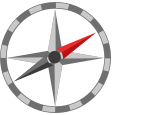** 추가 탐색 **

- 온라인 교육 과정[ Introduction to Linear Algebra with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-linear-algebra-with-matlab/linalg)에서 행렬 연산 및 기타 선형 대수 주제에 대해 자세히 알아볼 수 있습니다. 

- Symbolic Math에 대해 자세히 알아보려면 온라인 교육 과정 [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic)을 확인하세요. 

function eqs = Plot3DSystem(A,bvec,lims)
% This plots a 3D system of equations of the form Ax = b
    % Solve for z
    syms x y z
    xvec = [x; y; z];  
    eqs = A*xvec == bvec;
    f1 = solve(eqs(1),z);
    f2 = solve(eqs(2),z);
    f3 = solve(eqs(3),z);
    fm1 = matlabFunction(f1,"Vars",[x y]);
    fm2 = matlabFunction(f2,"Vars",[x y]);
    fm3 = matlabFunction(f3,"Vars",[x y]);
    % 플롯을 만듭니다.
    c = lines(5);
    figure('position',[0 0 600 600])
    fsurf(fm1,lims,"facecolor",c(1,:),"facealpha",0.5,"edgecolor","none")
    hold on;
    fsurf(fm2,lims,"facecolor",c(2,:),"facealpha",0.5,"edgecolor","none")
    fsurf(fm3,lims,"facecolor",c(3,:),"facealpha",0.5,"edgecolor","none")    
    if(det(A)~=0)
        x = A\bvec;
        plot3(x(1),x(2),x(3),"go","MarkerFaceColor","G")
    end
    hold off
    axis equal;
    view (10,30); 
    axis tight
    legend("eq1","eq2","eq3")
    xlabel("x")
    ylabel("y")
    zlabel("z")
end

function InvDialogue(k)
% 이것은
% 특정 행렬(아래 정의)의 행 축소를 살펴보는 대화를 생성합니다.
    AI = [];
    AIprev = AI;
    for i = 1:k
        switch i
            case 1
                text = "1. A와 I를 하나의 첨가 행렬로 함께 작성합니다.";    
                AI = sym([0.5 2 1 1 0 0; 1 2 -1 0 1 0; -1 0 -4 0 0 1]);
            case 2
                text = "2. 행 2를 행 3에 더합니다.";
                AI(3,:) = AI(3,:) + AI(2,:);
            case 3
                text ="3. -2*행 1을 행 2에 더합니다.";
                AI(2,:) = AI(2,:) + -2*AI(1,:);
            case 4
                text ="4. 행 1에 2를 곱합니다.";
                AI(1,:) = 2*AI(1,:) ;
            case 5
                text ="5. 행 2를 행 3에 추가합니다.";
                AI(3,:) = AI(3,:) + AI(2,:);
            case 6
                text = "6. 2번째 행을 -2로 나누고 3번째 행을 -8로 나눕니다.";
                AI(2,:) = AI(2,:)/-2;
                AI(3,:) = AI(3,:)/-8;
            case 7
                text = "7. 행 2에서 행 3*-1.5를 뺍니다.";
                AI(2,:) = AI(2,:) - 1.5*AI(3,:);
            case 8
                text = "8. 행 1에서 -4*행 2와 -2*행 3을 뺍니다.";
                AI(1,:) = AI(1,:) - 4*AI(2,:) - 2*AI(3,:);
            case 9
                text = "역행렬은 마지막 세 열에 포함되어 있습니다.";
            otherwise
                AI = sym([0.5 2 1; 1 2 -1; -1 0 -4]);
                k = 0;
                text = "0. 행렬 A:";
        end 
        if( i == k-1 )
            AIprev = AI; 
        end
    end
    
    AI = combine(AI);
    displayFormula("'" + text + " '")
    if(k == 9)
        AI46 = AI(:,4:6);
        displayFormula(["'A⁻¹ = '", "AI46"]);
    elseif (k == 1)
        displayFormula("AI");
    else      
        displayFormula(["AIprev" , "'→'" , "AI"])
    end
end

function correct = IsEqualCheck(UserSubmission, CorrectAnswer)
% 이 함수는 두 결과가 같은지 확인하고 피드백을 표시합니다.
    correct = true;
    if( isequal(UserSubmission, CorrectAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

% Suppress unusued suggestions
%#ok<*IJCL> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*NBRAK> 
%#ok<*NODEF>
%#ok<*NASGU> 